assignment1

function [X] = dtft(x, n, w)
% General DTFT using matrix-vector product
% x: signal values, row or column vector
% n: sample positions (must match x)
% w: vector of frequency points (rad/sample)

% 모양 맞추기
x = x(:).';     
n = n(:).';    

E = exp(-1j * (w(:) * n));   

% matrix-vector product
X = E * x.';    
end


assignment2

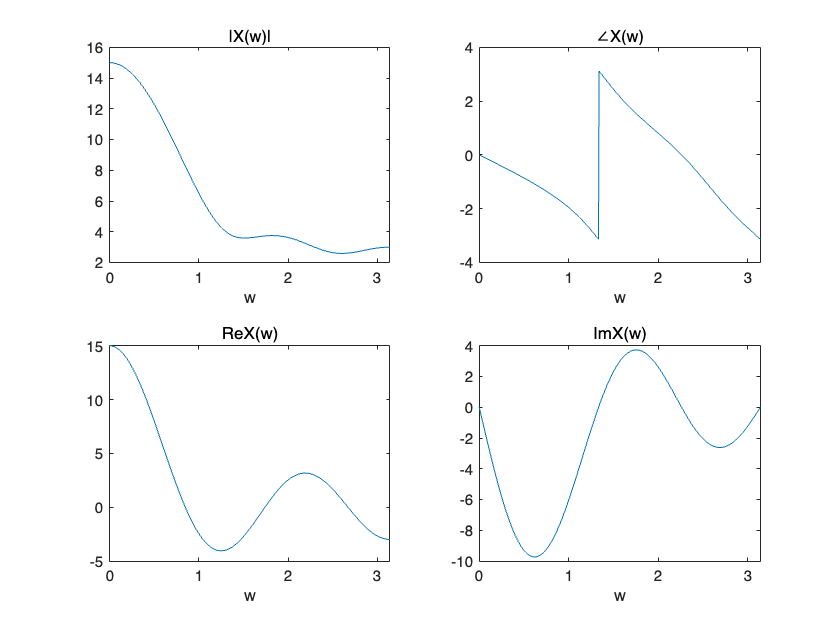


n = -1:3;
x = [1 2 3 4 5];
w = linspace(0, pi, 501);  

X = dtft(x, n, w);  % DTFT함수 이용해서 실행

% Plotting
figure;
subplot(2,2,1); plot(w, abs(X)); title('|X(w)|'); xlabel('w');
subplot(2,2,2); plot(w, angle(X)); title('∠X(w)'); xlabel('w');
subplot(2,2,3); plot(w, real(X)); title('Re{X(w)}'); xlabel('w');
subplot(2,2,4); plot(w, imag(X)); title('Im{X(w)}'); xlabel('w');

assignment3

% dt로 나타내기
n0 = -50:50;
k0=0:500;
k = 0:500;
w=pi*k/500;
% Ts=0.1ms
Ts1=0.0001;
xd1=sin(1000*pi*n0*Ts1);
% Ts=1ms
Ts2=0.001;
xd2=sin(1000*pi*n0*Ts2);
% Ts=0.01sec
Ts3=0.01;
xd3=sin(1000*pi*n0*Ts3);
%dtft 구하기
X1=dtft(xd1,n0,w);
2

ans = 2

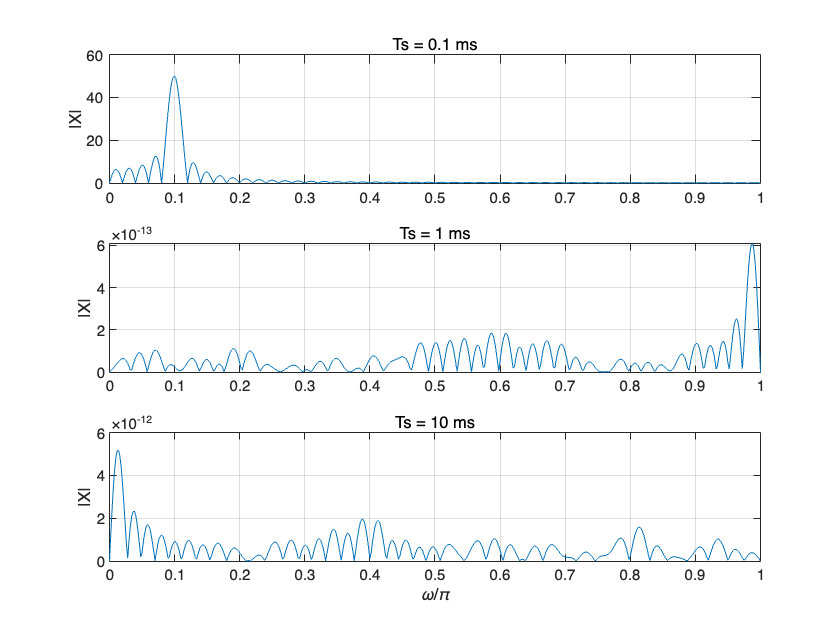

X2=dtft(xd2,n0,w);
X3=dtft(xd3,n0,w);
figure(2);
figure(2);
subplot(3,1,1);
plot(w/pi, abs(X1)); title('Ts = 0.1 ms'); ylabel('|X|'); grid on;
subplot(3,1,2);
plot(w/pi, abs(X2)); title('Ts = 1 ms'); ylabel('|X|'); grid on;
subplot(3,1,3);
plot(w/pi, abs(X3)); title('Ts = 10 ms'); ylabel('|X|'); xlabel('\omega/\pi');
ylabel('|X|'); grid on;